**Image Segmentation Notebook**

**Kuan-Min Lee**

**Thresholding Method:**

**Basic Theory explanation:**

**Citation: Lecture Automatic Thresholding**

We can change the **pixels of an image** to make the image easier to analyze.

In thresholding, we convert an image **from color or grayscale into binary image. Most Frequently, we use thresholding as a way to select area of interest of an image and ignore the parts we are not concerned with:**

**Relative Function: **

**imbinarize(I,method) function\**

**Image citation: Zanaty, E.. (2016). Medical Image Segmentation Techniques: An Overview. International Journal of informatics and medical data processing (JIMDP). 1. 1. **

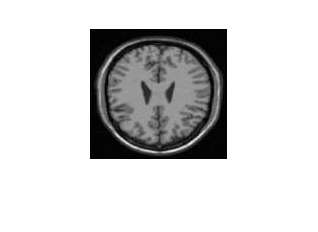

img=imread("original_brain_test_img.png"); % read in testing image for thresholding function
imshow(img)

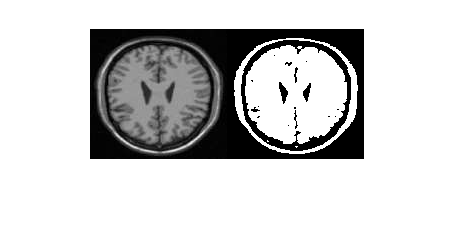

BW_img=imbinarize(img); % utilize the imbinarize function to get binarization version of the image
figure
imshowpair(img,BW_img,'montage')

**Testing of different mathods:**

**Global Threshold Computation Method:**

**Basic Idea [From Lecture: Automatic Thresholding]:**

The basic idea of global method of image binarization for image segmentation:

- Select an initial "guess" on threshold

- Compute the means of the **two regions (Below and above threshold)**

- Set the new threshold for next iteration as the **average between the two means**

- Repeat Step 2 and 3 untial the difference in T in successive iteration is **smaller than the predefined parameter**

BW_img_global=imbinarize(img,'global');
figure(1)
imshowpair(img,BW_img_global,'montage')

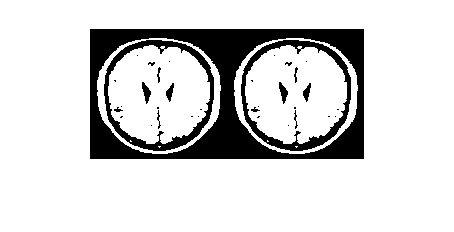

figure(2)
imshowpair(BW_img,BW_img_global,'montage')

In this testing, some of details part of  the image might be discarded since there is only one global threshold inserted into the algorithm.

**Adaptive Threshold Computation Method:**

**Basic Idea:**

Adaptive method focuses on calculating the locally adaptive image threshold chosed using **local first-order image statistics around each pixel.**

**Typical First order image statistical features:**

- **mean**

- **standard deviation**

- **skewness**

- **kortosis**

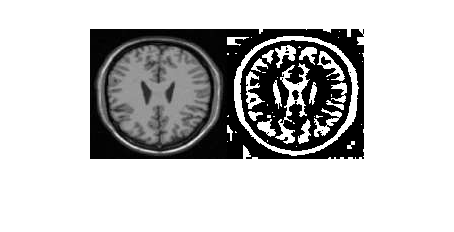

BW_img_adaptive=imbinarize(img,'adaptive');
figure(1)
imshowpair(img,BW_img_adaptive,'montage')

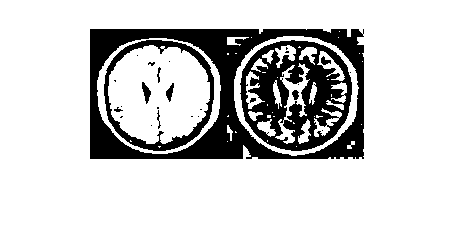

figure(2)
imshowpair(BW_img_global,BW_img_adaptive,'montage')

In this testing, some of the part of the brain is shown as black, which is resulted due to the mechanism of adaptivve method : calculating locally first order image statistics. As we performed image segmentation, this may result in wrong sorting.

**Testing with Multiple Color Object:**

**Image citation: Google map**

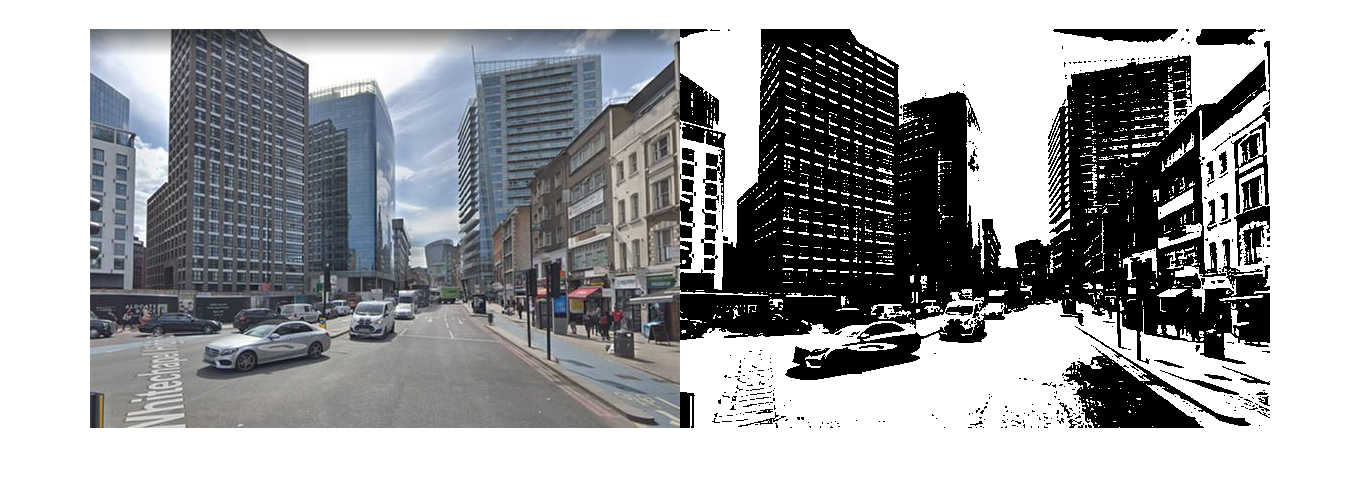

color_map=imread("google-maps-how-to-get-street-view-google-maps-2421144.jpg"); % read in sample color image
BW_map=rgb2gray(color_map); % convert it to grayscale
BW_map_global=imbinarize(BW_map); % conducting global thresholding
imshowpair(color_map,BW_map_global,'montage')

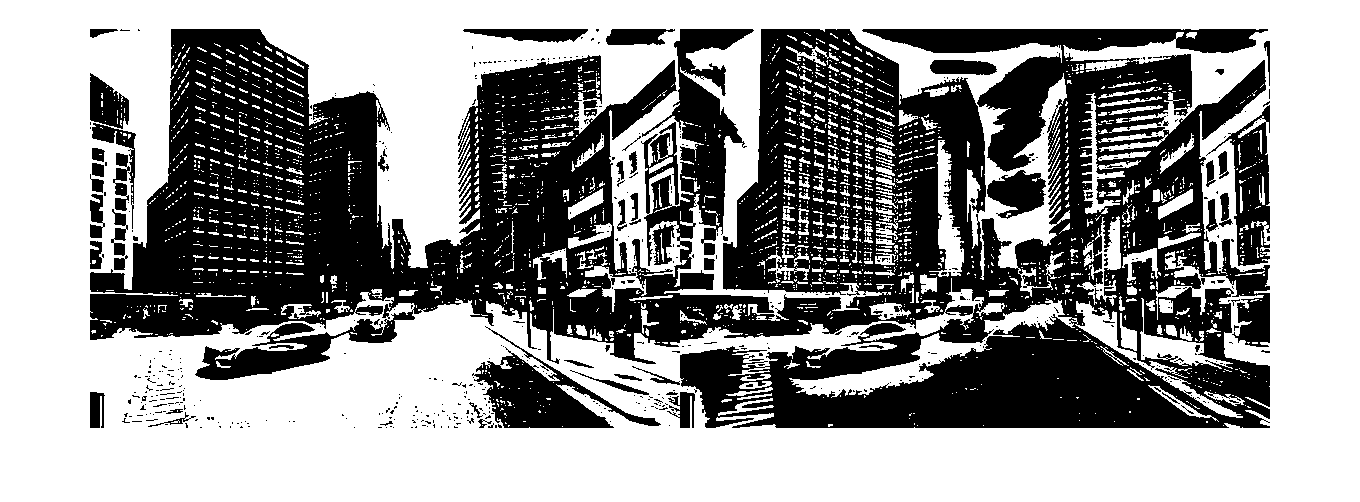

BW_map=rgb2gray(color_map); % convert it to grayscale
BW_map_adaptive=imbinarize(BW_map, 'adaptive'); % perfoem adaptive thresholding
imshowpair(BW_map_global,BW_map_adaptive,'montage')

From the above result, some of the region are sorted inappropriately. For example, the could part in the sky on the left and the shadow portion of the building on the left are blended into one region, which might cause problem in image segmentation. Therefore, thresholding method might not work well in a image which contains more complicated structures.

**Pros and Cons:**

**Pros:**

- Good for grayscale image, which has relative distinct mean in lightness intensity

- Good for separating binarized categories (like shadow and lightness)

**Cons:**

- Not easy to tell what category it is in each region (for example, in adaptive brain image, some brain region is shown as dark, which may be confused as shadow region)

- In global method, it has intention to lose the detial part of the image (for global grain image, some of the fold parts are eliminated)

- In adaptive method, it has intension to sort the regions into wrong categories (for adaptivve street image, the shadow part on the building and the cloud part in the sky) 

**Clustering Method:**

**Basic Theory explanations:**

**Citation: Lecture: Clustering Analysis and K-Mean by Nabel Gopalan from Goergia Tech.**

Segments an image into K number of clusters. The goal of clustering is to decide objects into groups and objects within a group **are more similar to those outside the group.**

**Relative function:**

**imagekmenas(I,k)**

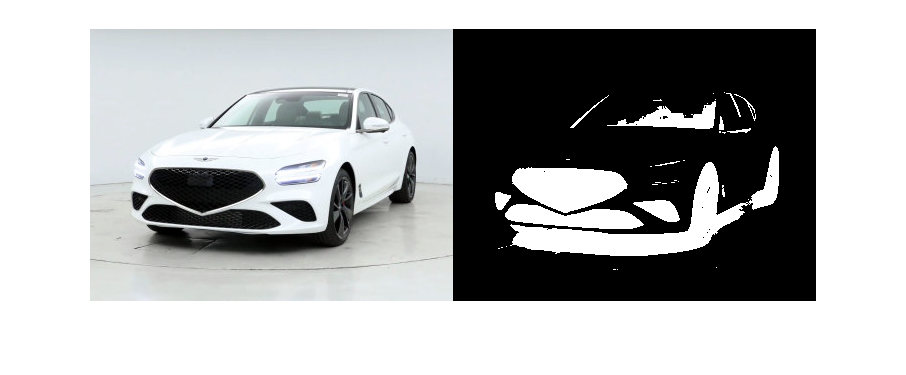

car_img=imread("car.jpg"); % read in sample image
car_img_BW=rgb2gray(car_img);
k_mean_car_img=imsegkmeans(car_img,2); % perform k mean clustering
imshowpair(car_img,k_mean_car_img,'montage')

From the above result, it can be seen that the k-mean algorithm sort the entire image into two regions (shadow and lightness) , which typically not what we want. Therefore, followed the procedure in matlab website, a set of 24 Gabor filters (6 wavelengths and 4 orientations) is inserted to improve its sorting ability.

Gaor filters can be seen as way for extracting texture feature in the image. It contains two controlling factor: Gabor wavelength and rotation angle. By inserting these two factors, Gabov filters will try to find out whether the texture with a certain frequency (wavelength and rotation angle) is existed withing the image:

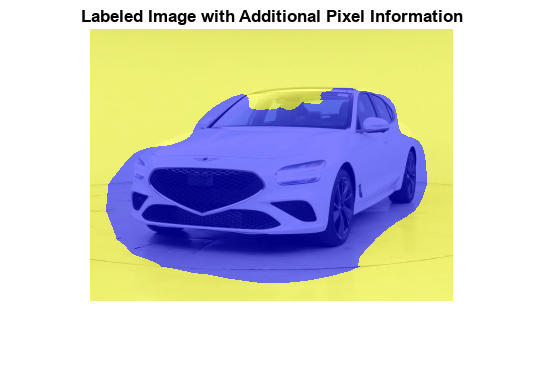

wavelength = 2.^(0:5) * 3; % insert three different wavelengths
orientation = 0:45:135; % insert 4 different orientation
g = gabor(wavelength,orientation);
car_img_BW = im2gray(im2single(car_img)); % convert it into grayscale
gabormag = imgaborfilt(car_img_BW,g); % conduct gabor filtering
% smoothe each gabor image (need fo
for i = 1:length(g)
    sigma = 0.5*g(i).Wavelength;
    gabormag(:,:,i) = imgaussfilt(gabormag(:,:,i),3*sigma); 
end
nrows = size(car_img,1);
ncols = size(car_img,2);
[X,Y] = meshgrid(1:ncols,1:nrows);
featureSet = cat(3,car_img_BW,gabormag,X,Y);
L2 = imsegkmeans(featureSet,2,"NormalizeInput",true);
C = labeloverlay(car_img,L2);
imshow(C)
title("Labeled Image with Additional Pixel Information")

From the above imrpvement, the category can be obseerved to perform better since it has successfully sort most of the car into the right category. 

**Pros and Cons:**

**Pros:**

- Unlike threshold mathod, it can perform **multi category segmentation**

- It can sort out the image based on the feature sets provided in the dataset (like the second part of the testing)

**Cons:**

- Its performance can be dependent on the **features provided in the dataset, which might be hard to utilize since we might not know what features should we go for**

- K-mean algorithm depends the **number of k being utilized into the algorithm, which might be confusing since the users might not know the appropriate number of k that should be used in the algorithm**

**Graph-Based Segmentation Method:**

**Basic Theory explanation:**

Image as graphs have node (vertex) for **every pixel. Edges happen between pairs of pixels (p,q), **and there's an **affinity weight** for each edge **(measure similarity)**.

**Different types of edges:**

- **Fully connected edges:**

**            Pros: **capture all pairwise similarities

            **Cons: infeasible for most image (too much computation)**

          2**.  Neighboring pixels edges:**

**            Pros: very fast to compute**

**            Cons: only capture very local interaction**

**          3. Local neighborhood edges:**

**             Reasonably fast graph still very sparse**

**Relative Function:**

**lazysnapping(Image,Label-matrix,foremask,backmask);**

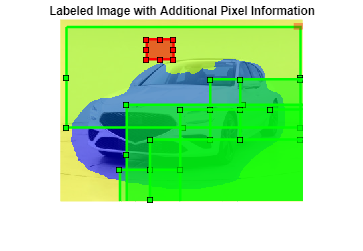

clear all
car_img=imread("car.jpg"); 
L=superpixels(car_img,500); % create label matrix (need more study on this function)
f = drawrectangle(gca,'Position',[135 180 270 180],'Color','g');
foreground = createMask(f,car_img);
b1 = drawrectangle(gca,'Position',[130 30 40 30],'Color','r');
b2 = drawrectangle(gca,'Position',[350 6 363 10],'Color','r');

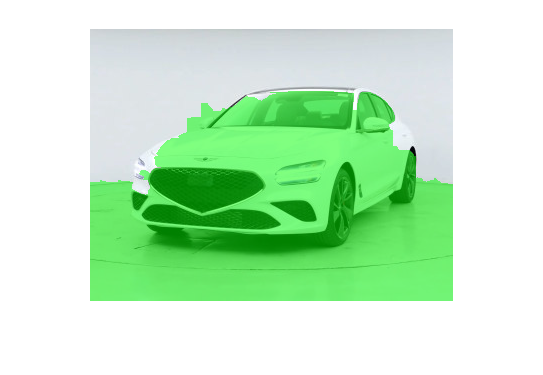

background = createMask(b1,car_img) + createMask(b2,car_img);
BW = lazysnapping(car_img,L,foreground,background);
imshow(labeloverlay(car_img,BW,'Colormap',[0 1 0]))

**Pros and Cons: **